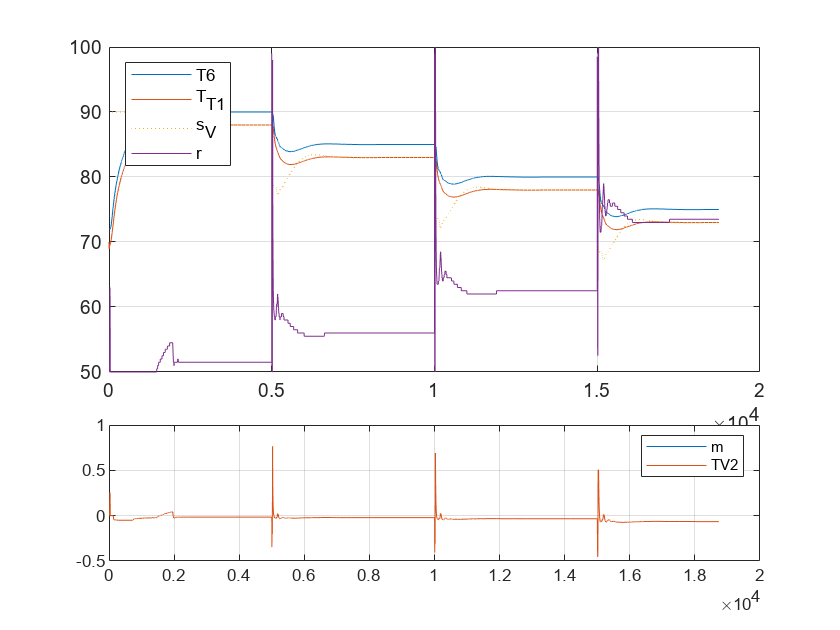

clear
eins = [1; 2; 3; 4];
zwei = 2 * eins;
drei = 3 * eins;
t = table(eins, zwei, drei);
writetable(t, 'tabellentest.txt');

while true
    try
        p = readtable("Raspberry pi git\ABB_pi\Monitor/log.txt");
    catch exception
    end


    
    subplot(3,1,[1 2])
    plot(p.T6)
    hold on
    plot(p.T_T_1)
    grid on
    plot(p.s_V,':')
    plot(50 + p.r * 50)
    hold off
    legend({'T6', 'T_T_1', 's_V', 'r'}, 'Location', 'northwest');
    
    subplot(3,1,3)
    plot(p.m)
    hold on
    plot(p.m)
    legend({'m','TV2'})
    %text(0.1,0.1,sprintf('s_V = %.2f', p.s_V(end)))
    grid on
    hold off
    drawnow

    pause(1)
end